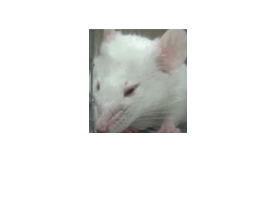

clc; clear; close all

img=imread('Test_rat_image3.png');
imshow(img)

I=rgb2gray(img);

%I_sobel=edge(I,'Sobel');
[I_test, threshold]=edge(I,'Canny');

Threshold

threshold

threshold =     0.0813    0.2031


I_edge=edge(I,'Canny',1.6* threshold);



Eye isolation

se90=strel('line',3,90);
se0=strel('line',3,0);
I_dilate=imdilate(I_edge,[se90 se0]);

I_fill=imfill(I_dilate,'holes');

I_erode=imerode(I_fill,[se90 se0]);
I_erode=imerode(I_erode,[se90 se0])

I_erode = 104×98 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

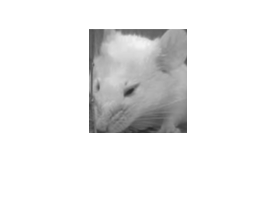

I_clear=imclearborder(I_erode);

imshow(I)

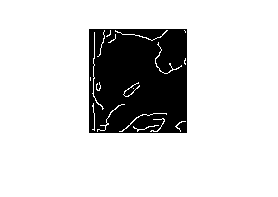

imshow(I_edge)

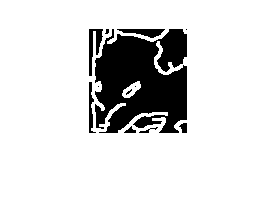


imshow(I_dilate)

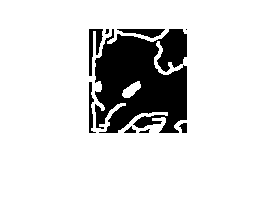

imshow(I_fill)

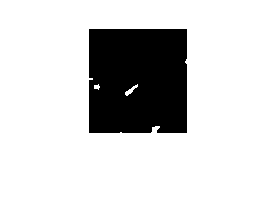

imshow(I_erode)

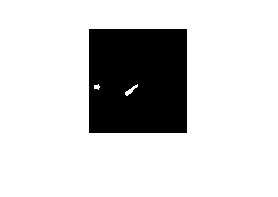

imshow(I_clear)

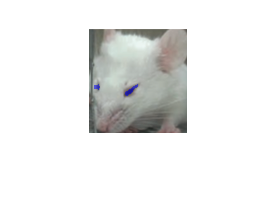


imshow(labeloverlay(img,I_clear))